F = zeros(Nnode,1);
F(bnd_501) = 1;
U = nan(Nnode,1);
U(bnd_401) = 0;

Ko = K;
Ko(bnd_401,:)=[];
Ko(:,bnd_401)=[];
F(bnd_401)=[];
% U_sc = inv(full(Ko))*F;
U_sc = Ko\F;

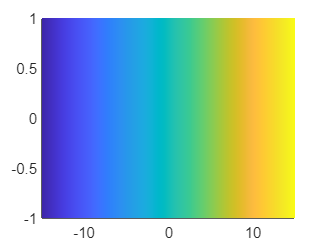

U(~(U==0))=U_sc;
% U = U_sc;
U(bnd_401) = 0;
plot_pcolor(Coordinate,U)

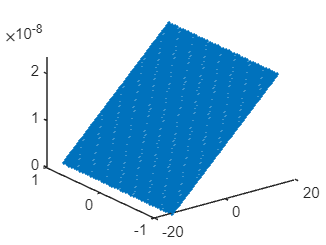

plot_plot3(Coordinate,U)